%FOR SIMULATING BUNCH OF STUFF LOOK UP advance() function. This allows you
%to individually advance it

# CubeSat Mission Analysis with Satellite Scenario

This example shows how to analyze mission geometry calculated during simulation using Aerospace Toolbox™ **Satellite Scenario** tools.

The analysis demonstrates how to:

- Create a satellite scenario using logged satellite position and attitude simulation data.

- Identify access between the onboard sensor and the imaging target.

- Visualize the scenario with **satelliteScenarioViewer.**

## Run the Simulation

Run the simulation if the simulation output object `out` does not exist. 

arch.model = "asbCubeSatArchModel";

if ~exist('out','var')
    %set_param('modelname', 'StopTime', '3000')
    open_system(arch.model);
    %simIn = Simulink.SimulationInput(arch.model);
    %a = 10
    %simIn = set_param(simIn, "StopTime", 86400/6);
    %a = get_param(arch.model, "StopTime")
    out = sim(arch.model);
    % out = sim(arch.model);
end

Updating initCond structure with initial values from stereotypes defined in:
  asbCubeSatArchModel/CubeSat Mission Enterprise (CubeSatProfile.CubeSatEnterprise)
  asbCubeSatArchModel/CubeSat Mission Enterprise/Space Segment/CubeSat Initial Orbit (CubeSatProfile.Orbit)
  asbCubeSatArchModel/CubeSat Mission Enterprise/Space Segment/CubeSat Initial Attitude (CubeSatProfile.Attitude)
Update complete.


Get simulation start date from the `CubeSatProfile.CubeSatEnterprise` stereotype definition in component `asbCubeSatArchModel/CubeSat Mission Enterprise`.

arch.cubeSatModel = systemcomposer.loadModel(arch.model);
mission.startDateJD = eval(getProperty(arch.cubeSatModel.lookup("Path", ...
    "asbCubeSatArchModel/CubeSat Mission Enterprise"), ...
    "CubeSatProfile.CubeSatEnterprise.MissionStartDate"));
mission.startDate = datetime(mission.startDateJD, ConvertFrom="juliandate");

## Extract States from Simulation Output

Extract the logged position, velocity, and attitude data from the simulation output structure.

logged.lla = out.yout{1}.Values.LatLonAlt;
logged.X_ecef = out.yout{1}.Values.X_ecef;
logged.V_ecef = out.yout{1}.Values.V_ecef;
logged.q_ecef2b = out.yout{1}.Values.q_ecef2b;

Set the start time of the **timetable** object to the mission start date.

logged.lla.Properties.StartTime = mission.startDate;
logged.lla = splitvars(logged.lla, "Data", NewVariableNames=["lat", "lon", "alt"]);
disp(head(logged.lla))

            Time             lat        lon         alt    
    ____________________    ______    _______    __________

    01-Jul-2019 11:00:00    5.3932     -27.24    1.6741e+06
    01-Jul-2019 11:00:01    5.4421    -27.256    1.6741e+06
    01-Jul-2019 11:00:02    5.4911    -27.272    1.6741e+06
    01-Jul-2019 11:00:02    5.4913    -27.272    1.6741e+06
    01-Jul-2019 11:00:02    5.4915    -27.272    1.6741e+06
    01-Jul-2019 11:00:02    5.4926    -27.272    1.6741e+06
    01-Jul-2019 11:00:02     5.498    -27.274    1.6741e+06
    01-Jul-2019 11:00:02    5.5253    -27.283    1.6741e+06



## Polulate the Satellite Scenario Object

Use **satelliteScenario** to create a new scenario. 

scenario = satelliteScenario(mission.startDate, mission.startDate + hours(72), 10);

Add a ground station to the scenario located at MathWorks in Natick.  This is the imaging target for the onboard sensor.

gs = groundStation(scenario, 42.2775, -71.2468, Name="GroundStation");  %This is in long lat
%This gets the ground stations location in ECEF
gsECEF = lla2ecef([42.2775 -71.2468, 0]);

Caculate slant range

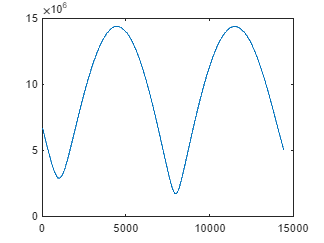

slantRange = sqrt(sum((logged.X_ecef.Data-gsECEF).^2, 2));
figure
plot(slantRange)

Calculate angle (This is the angle of the line that connects the satellite and the ground station and the plane tangent to the earth at the ground station)

In ECEF, the center of the earth is (0,0,0) so the equation of the plane can be found from the ground stations location in ECEF

line = logged.X_ecef.Data - gsECEF;


Add a satellite to the scenario from saved position and velocity **timetable** data.

sat = satellite(scenario, logged.X_ecef, logged.V_ecef, CoordinateFrame="ecef", Name="CubeSat");

%Orient the satellite using the saved attitude data from the model.

%pointAt(sat, logged.q_ecef2b, CoordinateFrame="ecef", Format="quaternion");

Add a gimbal and conical sensor to the ground station

gsGimbal = gimbal(gs, MountingLocation = [0;0;-1], MountingAngles=[0;180;0]);
gsConic = conicalSensor(gsGimbal, MountingLocation = [0;0;0.5]);
%This points the gimbal at the satellite
pointAt(gsGimbal, sat)
fieldOfView(gsConic);

Add a gimbal to the satellite. Attach a camera to the gimbal

satGimbal = gimbal(sat, MountingLocation = [0;0;0], MountingAngles = [0;0;0])

satGimbal =   Gimbal with properties:

                Name:  Gimbal 6
                  ID:  6
    MountingLocation:  [0; 0; 0] meters
      MountingAngles:  [0; 0; 0] degrees
      ConicalSensors:  [1x0 matlabshared.satellitescenario.ConicalSensor]
        Transmitters:  [1x0 satcom.satellitescenario.Transmitter]
           Receivers:  [1x0 satcom.satellitescenario.Receiver]
      CoordinateAxes:  [1x1 matlabshared.satellitescenario.CoordinateAxes]


satSensor = conicalSensor(satGimbal, MaxViewAngle=5); %only allow 5 degrees of error
fieldOfView(satSensor);
pointAt(satGimbal, gs);

## Add transmitter and receiver

gsTransmitter = transmitter(gsGimbal, "Name", "GS Transmitter", ...
    "MountingLocation", [0;0;1], ...
    "Frequency", 2.2e9, ...
    "Power", 50, ...
    "BitRate", 4.8);
gaussianAntenna(gsTransmitter, "DishDiameter", 3);
satReceiver = receiver(satGimbal, "MountingLocation", [0;0;0], "GainToNoiseTemperatureRatio", -19.3, "RequiredEbNo", 11.5);
gaussianAntenna(satReceiver, "DishDiameter", .2, "ApertureEfficiency", .45);

## Analyze access sat and Ground Station

Perform access analysis between the satellite and ground station.

acc = access(satSensor, gs);

Display intervals during which the satellite has line of sight of the ground station. (With 5 deg error)

accTable = accessIntervals(acc);
display(accTable);

accTable = 4×8 table
          Source              Target         IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    __________________    _______________    ______________    ____________________    ____________________    ________    __________    ________

    "Conical sensor 7"    "GroundStation"          1           01-Jul-2019 11:05:50    01-Jul-2019 11:27:00      1270         NaN          NaN   
    "Conical sensor 7"    "GroundStation"          2           01-Jul-2019 13:00:20    01-Jul-2019 13:24:40      1460         NaN          NaN   
    "Conical sensor 7"    "GroundStation"          3           02-Jul-2019 12:54:20    02-Jul-2019 14:47:40      6800     

## Add Link Analysis

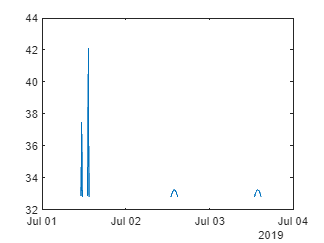

lnk = link(gsTransmitter, satReceiver);
[e, time] = ebno(lnk);
margin = e - satReceiver.RequiredEbNo;
figure
plot(time, margin);

### View scenario in Satellite Scenario Viewer

Open the Satellite Scenario Viewer to animate the scenario.

satelliteScenarioViewer(scenario);

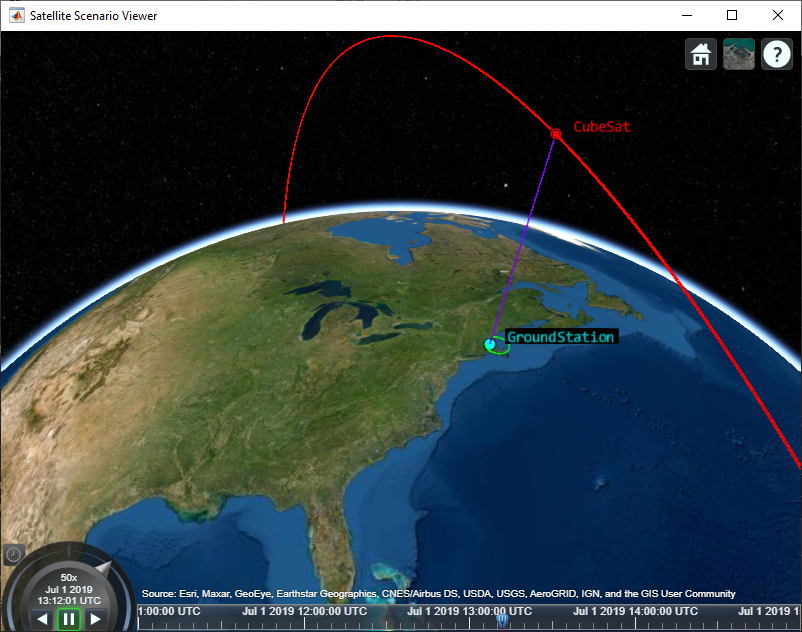

*Copyright 2021 The MathWorks, Inc.*